# Testing different models individually and comparing

## Setting up the signal

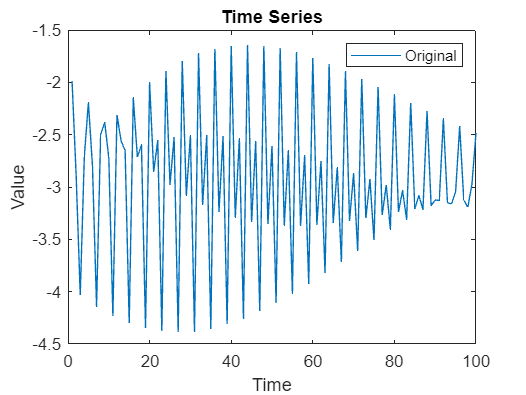

clear all;

addpath('./tensorlab/');

N = 100;
t = (1:N)';

% Determine option testing purposes
signal_option = 3;
noise_option = 1;

% Signal multiplicator
smul = 40*rand();

% Define base signals without decay and random addition
base_signal1 = sin(2 * pi * smul * 0.1 * t);
base_signal2 = sin(2 * pi * smul * 0.05 * t);
base_signal3 = sin(2 * pi * smul * 0.02 * t);

% Apply selected option
switch signal_option
    case 1
        % No decay or random addition
        signal1 = base_signal1;
        signal2 = base_signal2;
        signal3 = base_signal3;
    case 2
        % No random addition
        signal1 = base_signal1 .* exp(-0.01 * t);
        signal2 = base_signal2 .* exp(-0.01 * t);
        signal3 = base_signal3 .* exp(-0.01 * t);
    case 3
        % Everything (decay and random addition)
        signal1 = base_signal1 .* exp(-0.01 * t) + rand() * 10;
        signal2 = base_signal2 .* exp(-0.01 * t) - rand() * 10;
        signal3 = base_signal3 .* exp(-0.01 * t) + rand() * 10;
    case 4
        % No decay, random addition
        signal1 = base_signal1 + rand() * 10;
        signal2 = base_signal2 - rand() * 10;
        signal3 = base_signal3 + rand() * 10;
    otherwise
        error('Invalid option selected');
end

time_series = signal1+signal2+signal3;

% Plot the time series
figure;
plot(time_series);
legend({"Original"})
title('Time Series');
xlabel('Time');
ylabel('Value');

## AR vs CPD mean sum

num_experiments = 1;
components = 7;
num_predict = 1;
optimal_order = 20;


predictions_full = zeros(num_predict, num_experiments);
predictions_other = zeros(num_predict, num_experiments);
ground_truths = zeros(num_predict, num_experiments);

for exp=1:num_experiments
    disp("iter "+exp);
    ground_truths(:,exp) = time_series(end-num_predict+1:end);
   
    noisy_series = time_series + noise_option* (0.4*randn(N,1));

    training_series = noisy_series(1:end-num_predict);
    
    % Baseline model
    model2 = ar(training_series, optimal_order);
    predictions_full(:,exp) = forecast(model2, training_series,num_predict);

    % Testing model
    predictions_other(:,exp) = ar_cpd_ms(training_series,num_predict,optimal_order,components);

end

iter 1


disp("done!");

done!



rmse(predictions_full,ground_truths,2)

ans =    0.275117624561342


rmse(predictions_other,ground_truths,2)

ans =    0.303723344270660


## AR vs CPD mean full


num_experiments = 1;
components = 7;
num_predict = 1;
optimal_order = 20;


predictions_full = zeros(num_predict, num_experiments);
predictions_other = zeros(num_predict, num_experiments);
ground_truths = zeros(num_predict, num_experiments);

for exp=1:num_experiments
    disp("iter "+exp);
    ground_truths(:,exp) = time_series(end-num_predict+1:end);
   
    noisy_series = time_series + noise_option* (0.4*randn(N,1));

    training_series = noisy_series(1:end-num_predict);
    
    % Baseline model
    model2 = ar(training_series, optimal_order);
    predictions_full(:,exp) = forecast(model2, training_series,num_predict);

    % Testing model
    predictions_other(:,exp) = ar_cpd_mf(training_series,num_predict,optimal_order,components);

end
disp("done!");

rmse(predictions_full,ground_truths,2)
rmse(predictions_other,ground_truths,2)

## AR vs CPD columns

num_experiments = 1;
components = 3;
num_predict = 1;
optimal_order = 20;


predictions_full = zeros(num_predict, num_experiments);
predictions_other = zeros(num_predict, num_experiments);
ground_truths = zeros(num_predict, num_experiments);

for exp=1:num_experiments
    disp("iter "+exp);
    ground_truths(:,exp) = time_series(end-num_predict+1:end);


    noisy_series = time_series + noise_option* (0.4*randn(N,1));
    %ground_truths(:,exp) = noisy_series(end-num_predict+1:end);


    training_series = noisy_series(1:end-num_predict);
    
    % Baseline model
    model2 = ar(training_series, optimal_order);
    predictions_full(:,exp) = forecast(model2, training_series,num_predict);

    % Testing model
    predictions_other(:,exp) = ar_cpd_col(training_series,num_predict,10,components);

end

iter 1


    "Dimension of hankel: 12"    "Dimension of hankel: 12"    "Dimension of hankel: 77"



disp("done!");

done!



rmse(predictions_full,ground_truths,2)

ans =    0.247662004366879


rmse(predictions_other,ground_truths,2)

ans =    0.566975546899120


## AR vs SVD

num_experiments = 1;
components = 7;
num_predict = 1;
optimal_order = 20;


predictions_full = zeros(num_predict, num_experiments);
predictions_other = zeros(num_predict, num_experiments);
ground_truths = zeros(num_predict, num_experiments);

for exp=1:num_experiments
    disp("iter "+exp);
    ground_truths(:,exp) = time_series(end-num_predict+1:end);


    noisy_series = time_series + noise_option* (0.4*randn(N,1));
    %ground_truths(:,exp) = noisy_series(end-num_predict+1:end);


    training_series = noisy_series(1:end-num_predict);
    
    % Baseline model
    model2 = ar(training_series, optimal_order);
    predictions_full(:,exp) = forecast(model2, training_series,num_predict);

    % Testing model
    predictions_other(:,exp) = ar_svd(training_series,num_predict,10,components);

end

iter 1


H2D =   -1.343993001115481  -3.116374857318665  -4.103142822739436  -2.438062663064379  -2.547472576669544  -3.405947524727077  -3.537829922797942  -2.568996370703399  -2.401427089267813  -2.783768422433760  -4.492179167928272  -2.742489849462661  -2.876224265888427  -2.459254251112985  -4.805096913116476  -2.350835922829977  -2.725475102061109  -1.209140181381226  -3.886237736483828  -1.876628931819711  -2.054046292536093  -2.182518494691875  -4.441435056436324  -1.966456772287970  -2.900739406675009  -2.968672303573766  -4.473724734411058  -1.523566166312751  -2.810644568801249  -2.877293696303930  -5.083272283916188  -2.034827167417403  -3.277554839774205  -2.597273090027072  -3.739886838521512  -1.983226180076036  -3.185250635373971  -2.356114695992184  -4.324134615685198  -2.307598161656141  -3.704574253658611  -2.957554662859182  -3.327732382747796  -1.530397317498707  -3.469565560640708  -2.143888355412247  -3.993372137649942  -1.769681568923923  -3.245328756539195  -2.360380923

disp("done!");

done!



rmse(predictions_full,ground_truths,2)

ans =    0.802399899729299


rmse(predictions_other,ground_truths,2)

ans =    0.123825846578617


## AR vs SSD

num_experiments = 1;
components = 3;
num_predict = 1;
optimal_order = 10;


predictions_full = zeros(num_predict, num_experiments);
predictions_other = zeros(num_predict, num_experiments);
ground_truths = zeros(num_predict, num_experiments);

for exp=1:num_experiments
    disp("iter "+exp);
    ground_truths(:,exp) = time_series(end-num_predict+1:end);


    noisy_series = time_series + noise_option* (0.4*randn(N,1));
    %ground_truths(:,exp) = noisy_series(end-num_predict+1:end);


    training_series = noisy_series(1:end-num_predict);
    
    % Baseline model
    model2 = ar(training_series, optimal_order);
    predictions_full(:,exp) = forecast(model2, training_series,num_predict);

    % Testing model
    predictions_other(:,exp) = ar_ssd(training_series,num_predict,1,0.005,components,optimal_order);

end

iter 1


num_components =      3


Error using idmodel/forecast
The "InterSample" property must be a cell array of size Nu-by-Ne, where Nu = number of inputs and Ne = number of experiments in the data set.

Error in ar_ssd (line 52)
        pred_components(:,comp) = forecast(model_comp, component_series, num_predict);

disp("done!");

rmse(predictions_full,ground_truths,2)
rmse(predictions_other,ground_truths,2)